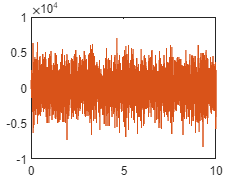

stim = P(1).antennal_movement(1,start_stim:stop_stim);
response  = P(1).gcfr(1, start_stim:stop_stim);
stim_len = length(stim);
t1 = linspace(0,10,stim_len);

STA_window = 0.03;
STA  = STA_analysis(P(i).raster, P(i).antennal_movement, STA_window, fs, start_stim, stop_stim);
autocorrStim = [];
powerLevel = [];

% autocorrStim = conv(stim,-stim);
% powerLevel = (1/stim_len)*sum(stim.^2);
% powerLevel = sum(autocorrStim)/(2*stim_len);
powerLevel = sum(periodogram(stim,[],length(stim),fs,'power'));
% powerLevel = sum(stim.^2)/stim_len
% powerLevel = max(autocorrStim);
meanFR = mean(response);

linear_pred = ((meanFR/powerLevel).*conv(stim,STA, 'same'));

figure;
plot(t1, response); hold on;
plot(t1, linear_pred);